We want to model the system using Euler-Lagrange modelling. We have two degrees of freedom $\theta_1$ and $\theta_2$.

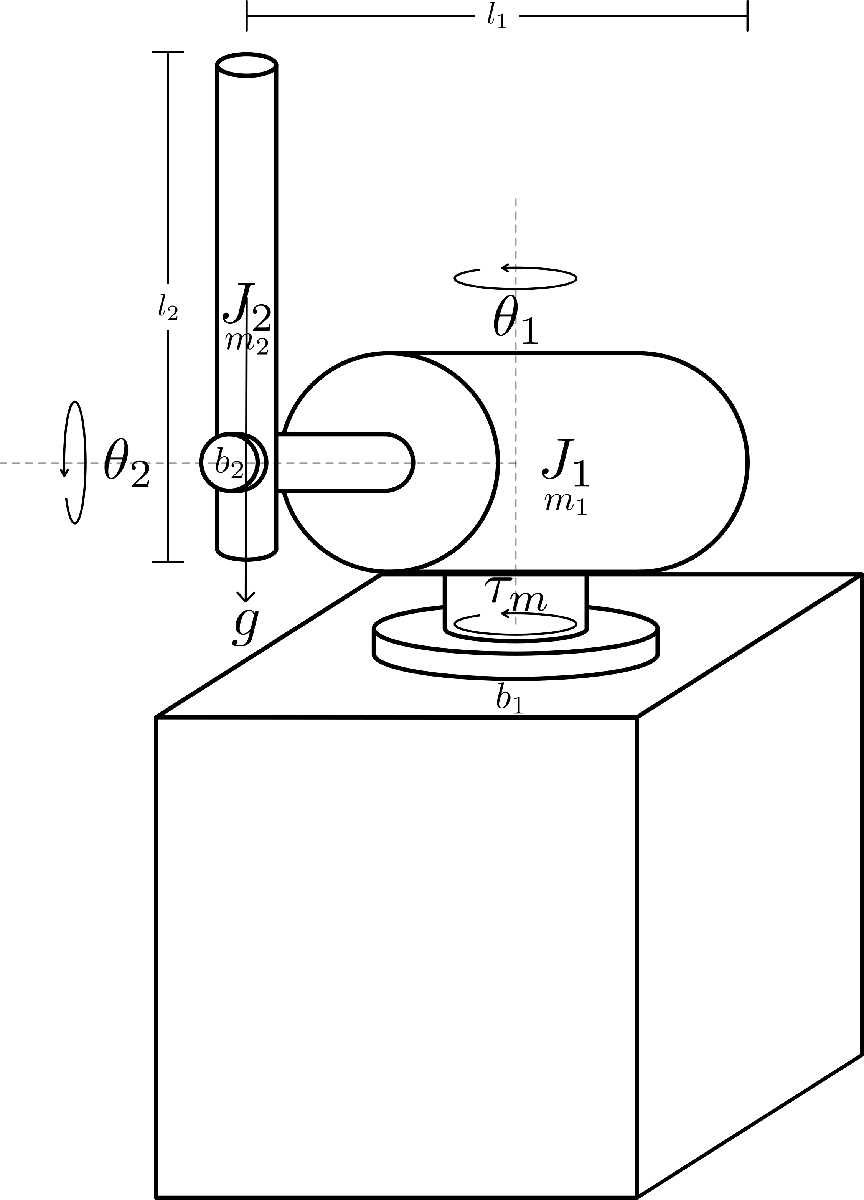

clc; clear; close all;

syms theta_1 theta_2 dtheta_1 dtheta_2 ddtheta_1 ddtheta_2 real
syms m_1 m_2 l_1 l_2 J_1 J_2 real
syms g real
syms b_1 b_2 tau_m real

q = [theta_1; theta_2];
dq = [dtheta_1; dtheta_2];
ddq = [ddtheta_1; ddtheta_2];

The following is from lecture 12 of Modellering

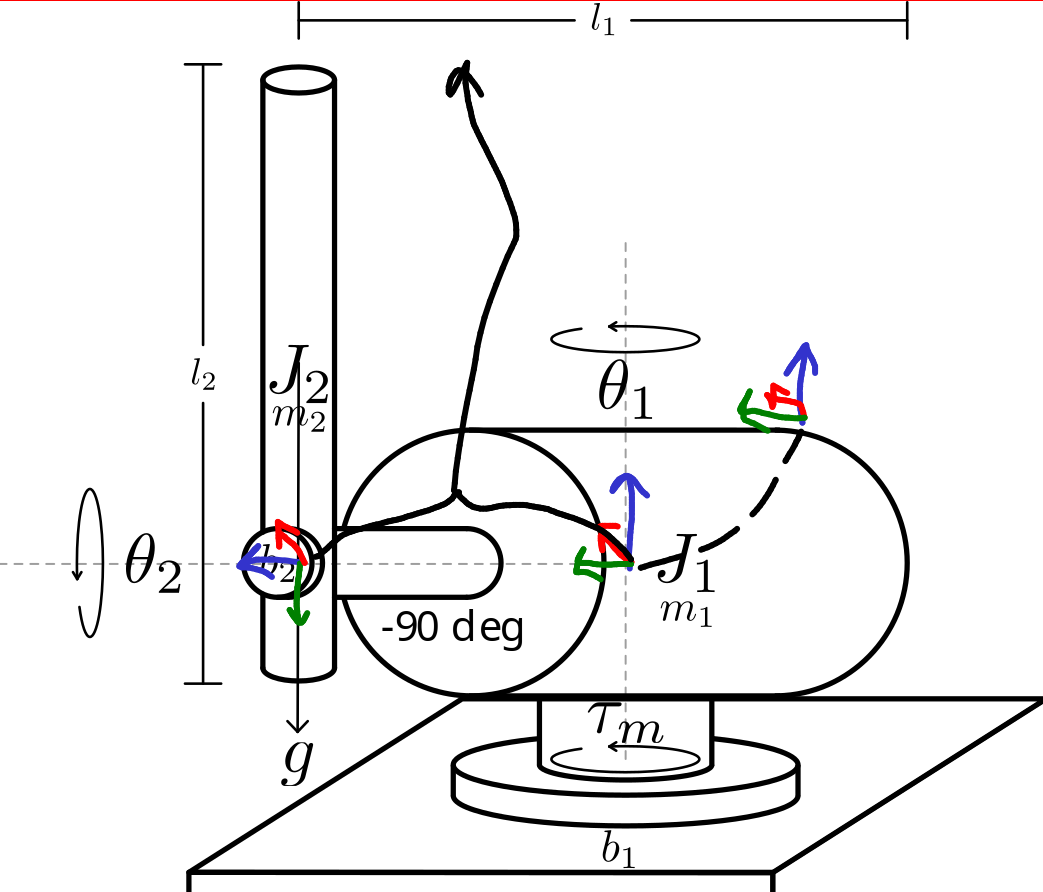

Frame 1 and Frame 2 have intersecting z-axis, so frame 1's x-axis should be the cross product of these two z-axis.

% DH parameters
alpha_0 = 0;
a_0 = 0;
d_0 = 0;

alpha_1 = -90; % angle from z_i to z_i+1 measured about x_i
a_1 = 0; % Offset along i x-axis
d_1 = 0; % Offset along i z-axis

alpha_2 = 0; % degrees
a_2 = 0;
d_2 = l_1/2; % Since we offset along the arm, this is the translation along z_2
% And since l_1 is from the end of the encoder to the joint of the
% pendulum, we will need to divide by 2 (approximately) to go from the
% middle of the encoder (frame 1 origin) to the origin of frame 2

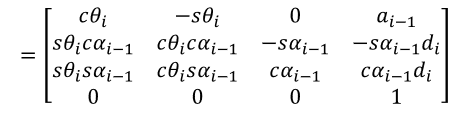

% Transformation matrix for links from DH parameters (L5 robotkinematik)
T_0_1=[              cos(theta_1)              -sin(theta_1)             0                 a_0;
       sin(theta_1)*cosd(alpha_0) cos(theta_1)*cosd(alpha_0) -sind(alpha_0) -sind(alpha_0)*d_1;
       sin(theta_1)*sind(alpha_0) cos(theta_1)*sind(alpha_0)  cosd(alpha_0)  cosd(alpha_0)*d_1;
                               0                          0              0                   1];

T_1_2 = [            cos(theta_2)              -sin(theta_2)             0                 a_1;
       sin(theta_2)*cosd(alpha_1) cos(theta_2)*cosd(alpha_1) -sind(alpha_1) -sind(alpha_1)*d_2;
       sin(theta_2)*sind(alpha_1) cos(theta_2)*sind(alpha_1)  cosd(alpha_1)  cosd(alpha_1)*d_2;
                               0                          0              0                   1];

T_0_2 = T_0_1*T_1_2;

% Position of origo in regards to base frame
p_0 = [0;0;0];
p_0_1 = T_0_1(1:3,4);
p_0_2 = T_0_2(1:3,4);

% Rotation matrices
R_0_1 = T_0_1(1:3, 1:3);
R_0_2 = T_0_2(1:3, 1:3);

% Position of link center in regards to base frame
p_0_c1 = p_0_1; % Center of mass is already at rotation point
p_0_c2 = R_0_2*[0; -l_2/2; 0]+p_0_2;

% Orientation of z-axis in regards to base frame
z_0 = [0;0;1];
z_0_1 = T_0_1(1:3, 3);
z_0_2 = T_0_2(1:3, 3);

% Jacobians for each joint (L12 modellering, and L10 robotkinematik)
J_P_1 = [cross(z_0, (p_0_c1 - p_0)) [0;0;0]];
J_P_2 = [cross(z_0, (p_0_c2 - p_0)) cross(z_0_1, (p_0_c2 - p_0_1))]

$$J\_P\_2 = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1} & \sigma_{1}\\ \sigma_{2} & \sigma_{2}\\ 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}-\frac{l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\\ \sigma_{2}=\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}-\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2} \end{array}$$


% We will also need to find the orientational Jacobian

% To find the full expression of kinetic energy
J_O_1 = [z_0 [0;0;0]]; % No joint affects the z-axis orientation of frame 1. The matrix is [z_0, 0]
J_O_2 = [z_0 z_0_1]; % Only joint 1 affects the z-axis of frame 2. The matrix is [z_0, z_0_1]

% To find the B-matrix, we will also need the inertia tensor of each link
% expressed in their own local frame.
% NEEED FILLING OUT!!
% We can express the inertia tensor as a diagonal matrix using the intertia
% moments of each link.
% For each link, the axis of symmetry is the y-axis
% From Modellering L8, latex page 13 we know, that the axis of symmetry is
% equal to I_y = I_x + I_z = 2*I_x
% We use J as the symbol for intertia moment instead of I.
I_1_local = diag([J_1/2, J_1, J_1/2]);
I_2_local = diag([J_2/2, J_2, J_2/2]);

% Since we know, that E_kin can be expressed using both the B-matrix, and
% the Jacobians, we need to isolate the B-matrix from the equation at the
% top of this section.
% B-matrix (L12 modellering)
B = m_1*J_P_1'*J_P_1 + m_2*J_P_2'*J_P_2 + J_O_1'*R_0_1*I_1_local*R_0_1'*J_O_1 + J_O_2'*R_0_2*I_2_local*R_0_2'*J_O_2

$$B = \begin{array}{l} \left(\begin{array}{cc} \frac{J_{1}}{2}+m_{2}\,{\left(\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\right)}^{2}+m_{2}\,{\left(\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\right)}^{2}+J_{2}\,{\cos\left(\theta_{2}\right)}^{2}+\frac{J_{2}\,{\sin\left(\theta_{2}\right)}^{2}}{2} & \sigma_{1}\\ \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{\left(\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\right)}^{2}+m_{2}\,{\left(\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\right)}^{2}+J_{2}\,{\cos\left(\theta_{2}\right)}^{2}+\frac{J_{2}\,{\sin\left(\theta_{2}\right)}^{2}}{2} \end{array}$$

E_kin_0 = simplify(1/2 * dq' * B * dq)

$$E\_kin\_0 = \frac{J_{1}\,{{\mathrm{dtheta}}_{1}}^{2}}{4}+\frac{3\,J_{2}\,{{\mathrm{dtheta}}_{1}}^{2}}{8}+\frac{3\,J_{2}\,{{\mathrm{dtheta}}_{2}}^{2}}{8}+\frac{{{\mathrm{dtheta}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dtheta}}_{1}}^{2}\,{l_{2}}^{2}\,m_{2}}{16}+\frac{{{\mathrm{dtheta}}_{2}}^{2}\,{l_{1}}^{2}\,m_{2}}{8}+\frac{{{\mathrm{dtheta}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}}{16}+\frac{3\,J_{2}\,{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}}{4}+\frac{J_{2}\,{{\mathrm{dtheta}}_{1}}^{2}\,\cos\left(2\,\theta_{2}\right)}{8}+\frac{J_{2}\,{{\mathrm{dtheta}}_{2}}^{2}\,\cos\left(2\,\theta_{2}\right)}{8}+\frac{{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,{l_{1}}^{2}\,m_{2}}{4}+\frac{{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,{l_{2}}^{2}\,m_{2}}{8}-\frac{{{\mathrm{dtheta}}_{1}}^{2}\,{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{16}-\frac{{{\mathrm{dtheta}}_{2}}^{2}\,{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{16}+\frac{J_{2}\,{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,\cos\left(2\,\theta_{2}\right)}{4}-\frac{{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8}$$

% The g vector is how gravity affects in either direction from the base
% frame. The gravity only affects the system in the base frames z-axis
% going downards. So that is
g_direction = [0; 0; -g];
E_pot_0 = -(m_1*g_direction'*p_0_c1 + m_2*g_direction'*p_0_c2)

$$E\_pot\_0 = \frac{g\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)}{2}$$

## Deriviation from corialis forces

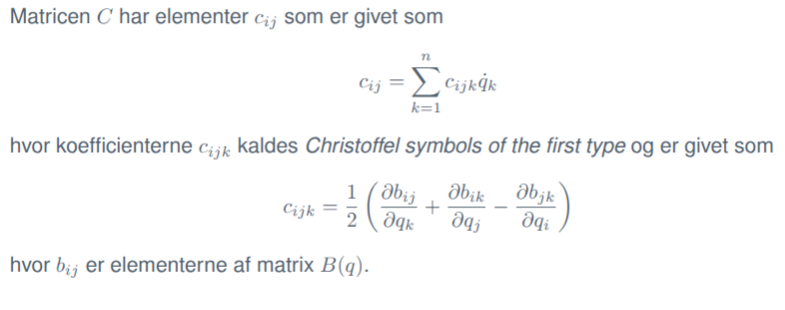

n = 2;
C = sym(zeros(n,n));
for i = 1:n
    for j = 1:n
        for k = 1:n
            c_ijk = 1/2 * (diff(B(i,j), q(k)) + diff(B(i,k), q(j)) - diff(B(j,k), q(i)));
            C(i,j) = C(i,j) + c_ijk * dq(k);
        end
    end
end

A Dynamical model for a robot can then be described as

We only need to calculate g(q), which is derived from E_pot as follows

g_q = [diff(E_pot_0, q(1)); diff(E_pot_0, q(2))];

% The tau vector is all generalised forces applied to the system. So that
% is input torque and friction
force_vec = [tau_m-b_1*dtheta_1; -b_2*dtheta_2] % Only joint 1 has a torque applied to it

$$force\_vec = \left(\begin{array}{c} \tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\\ -b_{2}\,{\mathrm{dtheta}}_{2} \end{array}\right)$$


%Thus
sys1 = B*ddq + C*dq + g_q == force_vec

$$sys1 = \begin{array}{l} \left(\begin{array}{c} {\mathrm{ddtheta}}_{1}\,\left(\frac{J_{1}}{2}+m_{2}\,{\sigma_{8}}^{2}+m_{2}\,{\sigma_{9}}^{2}+\sigma_{7}+\sigma_{6}\right)-{\mathrm{dtheta}}_{2}\,\left({\mathrm{dtheta}}_{2}\,\left(\sigma_{5}+\sigma_{4}-\sigma_{3}\right)+{\mathrm{dtheta}}_{1}\,\sigma_{1}\right)+{\mathrm{ddtheta}}_{2}\,\sigma_{2}-{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,\sigma_{1}=\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\\ \sigma_{1}\,{{\mathrm{dtheta}}_{1}}^{2}+\left(\frac{\sigma_{3}}{2}-\frac{\sigma_{4}}{2}-\frac{\sigma_{5}}{2}\right)\,{{\mathrm{dtheta}}_{2}}^{2}+{\mathrm{ddtheta}}_{1}\,\sigma_{2}+{\mathrm{ddtheta}}_{2}\,\sigma_{2}-\frac{g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}=-b_{2}\,{\mathrm{dtheta}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{5}}{2}+\frac{\sigma_{4}}{2}-\frac{\sigma_{3}}{2}\\ \sigma_{2}=m_{2}\,{\sigma_{8}}^{2}+m_{2}\,{\sigma_{9}}^{2}+\sigma_{7}+\sigma_{6}\\ \sigma_{3}=l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sigma_{8}\\ \sigma_{4}=l_{2}\,m_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sigma_{9}\\ \sigma_{5}=J_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{6}=\frac{J_{2}\,{\sin\left(\theta_{2}\right)}^{2}}{2}\\ \sigma_{7}=J_{2}\,{\cos\left(\theta_{2}\right)}^{2}\\ \sigma_{8}=\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}+\frac{l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\\ \sigma_{9}=\frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}-\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2} \end{array}$$

% We can isolate ddq, to get the following
ddq_calculated = inv(B)*(force_vec-C*dq-g_q);

% Next we setup the state and system vectors
% State space vectors
x = [q; dq];

% System vectors
dx = [dq; ddq];

% Input vector
tau_vec = [tau_m; 0]; % Only joint 1 is affected by torque

% The state space system is then
ss_sys = simplify([dq; ddq_calculated] + [0 0; 0 0; inv(B)]*force_vec*tau_m) % Det er jo mega langt...

## Time domain models

We now try to write up state space models for the system, that can later be converted to transfer functions.

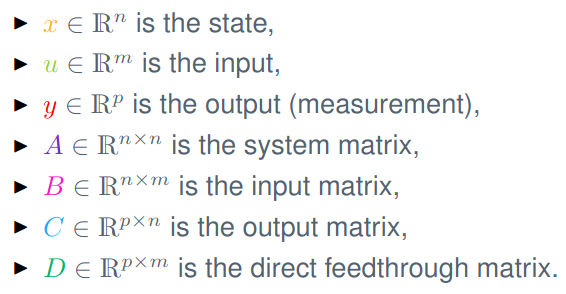

We will want to use the torque $\tau_m$ as an input and get the angular velocity of the pendulum $\dot{\theta_2 }$ as an output. We want this to be zero. We also want the angle $\theta_2$ to be 180 degrees (but this is for another time...)

% State space vectors
x_1 = [theta_1; dtheta_1];
x_2 = [theta_2; dtheta_2];
x = [x_1; x_2];

% System vectors
dx_1 = [dtheta_1; ddtheta_1];
dx_2 = [dtheta_2; ddtheta_2];
dx = [dx_1; dx_2];

% A matrix (found by isolating ddtheta in the system formulars)
sys1_A = isolate(sys1, ddtheta_1)
sys2_A = isolate(sys2, ddtheta_2)
%A = [0 1 0 0;
 %    0 -b_1/(m_2*l_1^2+J_1) %sin(theta_2)???? %hvordan pokker skal jeg opdele dtheta_2 udtrykket?]